%% SERVOSISTEMA CON OBSERVADOR PARA DOS TANQUES ACOPLADOS
% Este script:
% 1. Carga R1, R2 y A_tanque
% 2. Construye A, B, C, D
% 3. Diseña K para realimentación de estados
% 4. Diseña L para el observador
% 5. Calcula Nbar para seguimiento de referencia
% 6. Simula el sistema completo usando estados estimados
% 7. Grafica salida, estados reales/estimados y señal de control

clear; clc; close all;

%% 1) CARGAR PARÁMETROS
if ~isfile('parametros_tanques.mat')
    error(['No se encontró el archivo parametros_tanques.mat. ' ...
           'Primero ejecuta el script de cálculo de R1 y R2.']);
end

load('parametros_tanques.mat');

if ~exist('R1','var') || ~exist('R2','var') || ~exist('A_tanque','var')
    error('Faltan variables necesarias en parametros_tanques.mat');
end

A_t = A_tanque;

%% 2) MATRICES DEL SISTEMA
A = [ -1/(A_t*R1),              1/(A_t*R1);
       1/(A_t*R1),  -(1/(A_t*R1) + 1/(A_t*R2)) ];

B = [1/A_t;
     0];

C = [0 1];

D = 0;

disp('Matriz A:'); disp(A);

Matriz A:
   -0.0615    0.0615
    0.0615   -0.1053



disp('Matriz B:'); disp(B);

Matriz B:
   44.4444
         0



disp('Matriz C:'); disp(C);

Matriz C:
     0     1



disp('Matriz D:'); disp(D);

Matriz D:
     0




%% 3) PARÁMETROS QUE PUEDES CAMBIAR
href = 0.15;   % referencia [m]
Ts_obj = 20;   % tiempo de establecimiento deseado del servosistema [s]
zeta   = 0.7;  % amortiguamiento deseado

factor_observador = 8;   % qué tan rápido será el observador frente a la planta

% Condiciones iniciales
x0_real = [0; 0];          % estados reales iniciales
x0_est  = [0.02; 0.01];    % estados estimados iniciales

% Tiempo de simulación
t = 0:0.1:200;

%% 4) DISEÑO DE K
wn = 4/(zeta*Ts_obj);

p1 = -zeta*wn + 1j*wn*sqrt(1-zeta^2);
p2 = -zeta*wn - 1j*wn*sqrt(1-zeta^2);

polos_control = [p1 p2];

K = place(A,B,polos_control);

disp('Ganancia K del servosistema:');

Ganancia K del servosistema:


disp(K);

    0.0052    0.0199




%% 5) CÁLCULO DE Nbar
Nbar = -inv(C * inv(A - B*K) * B);

disp('Precompensador Nbar:');

Precompensador Nbar:


disp(Nbar);

    0.0299




%% 6) DISEÑO DEL OBSERVADOR
polos_planta = eig(A);
polos_obs = factor_observador * polos_planta;

L = place(A', C', polos_obs)';

disp('Ganancia del observador L:');

Ganancia del observador L:


disp(L);

    1.5938
    1.1679




disp('Polos del observador:');

Polos del observador:


disp(eig(A - L*C));

   -0.1450
   -1.1897




%% 7) SISTEMA COMPLETO: PLANTA + OBSERVADOR
% Planta:
% x_dot = A*x + B*u
%
% Observador:
% xhat_dot = A*xhat + B*u + L(y - C*xhat)
%
% Ley de control:
% u = -K*xhat + Nbar*r
%
% Entonces:
% x_dot    = A*x + B(-K*xhat + Nbar*r)
% xhat_dot = A*xhat + B(-K*xhat + Nbar*r) + L(C*x - C*xhat)

A_ext = [ A          -B*K;
          L*C   A - B*K - L*C ];

B_ext = [ B*Nbar;
          B*Nbar ];

C_ext = [C  zeros(size(C))];   % salida real y = Cx
D_ext = 0;

sys_ext = ss(A_ext, B_ext, C_ext, D_ext);

%% 8) SIMULACIÓN
r = href * ones(size(t));

x0_ext = [x0_real;
          x0_est];

[y, t_out, x_ext] = lsim(sys_ext, r, t, x0_ext);

% Extraer estados
h1_real = x_ext(:,1);
h2_real = x_ext(:,2);
h1_est  = x_ext(:,3);
h2_est  = x_ext(:,4);

%% 9) CÁLCULO DE LA SEÑAL DE CONTROL
u = zeros(length(t_out),1);

for k = 1:length(t_out)
    xhat_k = [h1_est(k); h2_est(k)];
    rk = r(k);
    u(k) = -K*xhat_k + Nbar*rk;
end

u_Lh = u * 3600 * 1000;

%% 10) ERRORES DE ESTIMACIÓN
e1 = h1_real - h1_est;
e2 = h2_real - h2_est;

fprintf('---------------------------------------------\n');

---------------------------------------------


fprintf('ERROR FINAL DE ESTIMACIÓN\n');

ERROR FINAL DE ESTIMACIÓN


fprintf('e1 final = %.8e m\n', e1(end));

e1 final = -3.27515792e-15 m


fprintf('e2 final = %.8e m\n', e2(end));

e2 final = -1.66533454e-16 m


fprintf('---------------------------------------------\n\n');

---------------------------------------------




%% 11) ERROR FINAL DE SEGUIMIENTO
error_final = href - y(end);

fprintf('Error final de seguimiento:\n');

Error final de seguimiento:


fprintf('error_final = %.8e m\n', error_final);

error_final = 6.93889390e-16 m


fprintf('error_final = %.4f cm\n\n', error_final*100);

error_final = 0.0000 cm




%% 12) INFORMACIÓN DE DESEMPEÑO
info = stepinfo(y, t_out, href);

disp('Información de desempeño:');

Información de desempeño:


disp(info);

         RiseTime: 7.5415
    TransientTime: 20.7828
     SettlingTime: 20.7828
      SettlingMin: 0.1354
      SettlingMax: 0.1565
        Overshoot: 4.3086
       Undershoot: 4.6736e-20
             Peak: 0.1565
         PeakTime: 15.6000



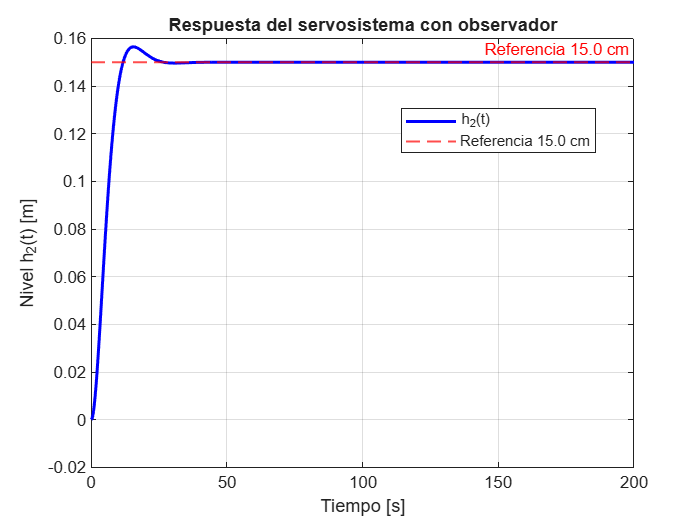


%% 13) GRÁFICA DE LA SALIDA
texto_ref = sprintf('Referencia %.1f cm', href*100);

figure;
plot(t_out, y, 'b', 'LineWidth', 1.8); hold on;
yline(href, '--r', texto_ref, 'LineWidth', 1.2);
grid on;
title('Respuesta del servosistema con observador');
xlabel('Tiempo [s]');
ylabel('Nivel h_2(t) [m]');
legend('h_2(t)', texto_ref, 'Location', 'best');


%% 14) ESTADOS REALES Y ESTIMADOS
figure;
plot(t_out, h1_real, 'b', 'LineWidth', 1.8); hold on;
plot(t_out, h1_est, '--r', 'LineWidth', 1.8);
grid on;
title('Comparación h_1 real vs estimado');
xlabel('Tiempo [s]');
ylabel('Nivel [m]');
legend('h_1 real', 'h_1 estimado', 'Location', 'best');

figure;
plot(t_out, h2_real, 'b', 'LineWidth', 1.8); hold on;
plot(t_out, h2_est, '--r', 'LineWidth', 1.8);
grid on;
title('Comparación h_2 real vs estimado');
xlabel('Tiempo [s]');
ylabel('Nivel [m]');
legend('h_2 real', 'h_2 estimado', 'Location', 'best');

%% 15) ERROR DE ESTIMACIÓN
figure;
plot(t_out, e1, 'm', 'LineWidth', 1.8); hold on;
plot(t_out, e2, 'g', 'LineWidth', 1.8);
grid on;
title('Error de estimación del observador');
xlabel('Tiempo [s]');
ylabel('Error [m]');
legend('e_1 = h_1 - \hat{h}_1', 'e_2 = h_2 - \hat{h}_2', 'Location', 'best');

%% 16) SEÑAL DE CONTROL
figure;
plot(t_out, u_Lh, 'LineWidth', 1.8);
grid on;
title('Señal de control del servosistema con observador');
xlabel('Tiempo [s]');
ylabel('Caudal de control [L/h]');

%% 17) POLOS DEL SISTEMA CONTROLADO
polos_cerrados_control = eig(A - B*K);

disp('Polos del control por estados:');

Polos del control por estados:


disp(polos_cerrados_control);

  -0.2000 + 0.2040i
  -0.2000 - 0.2040i




figure;
plot(real(polos_cerrados_control), imag(polos_cerrados_control), 'bx', ...
    'MarkerSize', 10, 'LineWidth', 2);
grid on;
title('Polos del sistema controlado A-BK');
xlabel('Parte real');
ylabel('Parte imaginaria');